# A singular optimal control problem using C.R. Heirdrich's method

[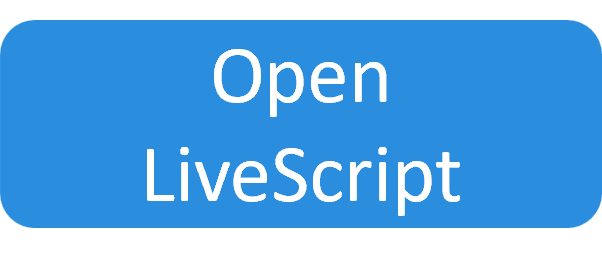](matlab:dxdzds.file='regularization_GRCO';dxdzds.outFile=fullfile(pwd,dxdzds.file); copyfile(which(['user_' dxdzds.file]),[dxdzds.outFile '.mlx']);open(dxdzds.outFile);clear dxdzds;)

In this example we use C.R. Heirdrich's method to regularize a singular optimal control problem [1]. This example uses the continuation procedure toolbox to compute a numerical solution and display the solution during the continuation procedure.

## Considered problem & method

### Original problem

The criterion to be minimized over $\left\lbrack 0,T\right\rbrack$, with $T=10s$, is :

$J=\int_0^T {x\left(t\right)}^2 \textrm{dt}$                                     (1)

The system dynamics is :

$\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}=-x\left(t\right)+u\left(t\right)$                            (2)

The control constraint is :

$u\left(t\right)\in \left\lbrack \underline{u} ,\bar{u} \right\rbrack$                                        (3)

The boundary condition is :

$x\left(0\right)=x_0$;$x\left(T\right)=x_T$                           (4)

The code used for the boundary condition is given here.

Numerical values : $x_0 =1$, $x_T =5$,  $\underline{u} =-5$ and $\bar{u} =5$.

% Problem parameters
clearvars;close all; clc
T=10;x0=1;xT=4;umin=-5;umax=5;
c0=(umin+umax)/2;c1=(umax-umin)/2;

Let us denote $p\left(t\right)$ the co-state, the Hamiltonian associated with the problem is:

$H\left(x,u,p\right)=$${x\left(t\right)}^2$+$p\left(t\right)\left(-x\left(t\right)+u\left(t\right)\right)$    (5)

The Hamiltonian is afine in the control, we can write:

$H\left(x,u,p\right)=H_0 +H_1 u\left(t\right)$                      (6)

with $H_0 ={x\left(t\right)}^2 -p\left(t\right)x\left(t\right)$ and $H_1$=$-p\left(t\right)$.

This Hamiltonian being affine in the control, the control $u$ is bang-bang, but one or more singular arcs may occur if $p\left(t\right)=0$ holds for a non null intervall of time.

### Regularization

We now introduce the change of variable needed for the regularization [1] where $u_r$ is the new control variable and $\varepsilon$ a regularization term.

$u\left(t\right)=c_1 \cdot \frac{2}{\pi }\textrm{atan}\left(\frac{u_r \left(t\right)}{\varepsilon }\right)+c_0$                                      (7)

with $c_0 =\frac{\bar{u} +\underline{u} }{2}$ and $c_1 =\frac{\bar{u} -\underline{u} }{2}$

A regularization term $L_{\textrm{reg}}$ is added to the criterion (1) :

$J=\int_0^T \left\lbrack {x\left(t\right)}^2 +L_{\textrm{reg}} \left(u_r \left(t\right)\right)\right\rbrack \textrm{dt}$                                       (8)

with $L_{\textrm{reg}} \left(u_r \left(t\right)\right)=c_1 \cdot \frac{\varepsilon }{\pi }\cdot \ln \left(1+\frac{u_r \left(t\right)²}{\varepsilon ²}\right)$

Then the optimal control is :

$u_r \left(t\right)=-H_1 =-p\left(t\right)$                                                    (9)

So the actual control value is :

$u\left(t\right)=c_1 \cdot \textrm{atan}\left(\frac{u_r -p\left(t\right)}{\varepsilon }\right)+c_0$                                      (10)

The code for the Hamiltonian minimization is given below.

The optimal costate dynamics is:

$\frac{\textrm{dp}\left(t\right)}{\textrm{dt}}=-\frac{\partial H}{\partial x}=-2x\left(t\right)+p\left(t\right)$                                      (11)

Finally, the Boundary Value Problem to be solved can be formulated using $Y\left(t\right)=\left(\begin{array}{c}
x\left(t\right)\\
p\left(t\right)
\end{array}\right)$.

$\frac{\textrm{dY}\left(t\right)}{\textrm{dt}}=\left(\begin{array}{c}
\frac{\textrm{dx}\left(t\right)}{\textrm{dt}}\\
\frac{\textrm{dp}\left(t\right)}{\textrm{dt}}
\end{array}\right)=\left(\begin{array}{c}
-x\left(t\right)+c_1 \cdot \textrm{atan}\left(\frac{-p\left(t\right)}{\varepsilon }\right)+c_0 \\
-2x\left(t\right)+p\left(t\right)
\end{array}\right)$                                     (12)

The corresponding code is given below.

## Problem solving using continuation procedure

### Using a first continuation procedure to bring initial & final states to their expected values

We first initialize the BVP problem with a steady solution $x\left(t\right)=0$, $p\left(t\right)=0$ and we modify temporarily $x_0 =x_T =0$ so that the provided initial solution is optimal.

% Initialization of the BVP at steadystate
nInit=100;
solInit.x=linspace(0,T,nInit);
solInit.y=repmat([0;0],[1 nInit]);

- We now define $x_0$ and $x_T$ as continuation procedure paramters whereas we set $\varepsilon$, $c_0$ and $c_1$ as fixed parameters.

paramStart.x0=0; paramEnd.x0=x0;
paramStart.xT=0; paramEnd.xT=xT;
fixedParams.epsi=100;fixedParams.c0=c0;fixedParams.c1=c1;

Each iteration of the continuation procedure consists in solving a boundary value problem with one of the available Matlab BVP solver. 

We first define the options of the BVP solver. Here a very poor accuracy is used, to reduce computation time (the accuracy of the final solution will be later improved).

bvpOpt=bvpset('RelTol',1e-2,'AbsTol',1e-4);

We also need two additionnal functions:

- generateFodeFcn : to generate a handle to the BVP dynamics that uses the current value of the continuation parameters

- generateBCFcn : to generate a handle to the BVP boundary conditions that uses the current value of the continuation parameters

Finally, we can define the problem to be solved by the continuation procedure. In the parameter, we aslo provide the solver `bvpOptions`.

problem=bvp4or5c("bvp5c",@generateFodeFcn,@generateBCFcn,bvpOptions=bvpOpt);

Now we can perform the first continuation procedure to bring the initial & final states to their expected values. First we define a scheduler that manages the smooth transition of the parameters from their initial value paramStart to their final value paramEnd.

scheduler=linearScheduler(paramStart,paramEnd,fixedParams=fixedParams, ...
    beta=1.2,initialDelta=0.1,deltaMin=0.01);

plotFigFcn : to plot the solution obtained at every iteration

cont=continuationProcedure(problem,scheduler,solInit,"plotFigFcn",@plotFigFcn,...
    "modifySolutionFcn",@modifySolutionFcn,'strIter','x0 & xT',...
    "preIterPrintFcn",@preIterPrintFcnx0xT);
cont.run;

Now we have a solution of the BVP for a very large $\rho$ value. We need to bring this value down to a very small value to solve the original problem.

We will use the last computed solution as the initial solution of the second continuation procedure:

solInit=cont.sol;

### Using a second continuation procedure to decrease `epsi` to a very small value

We now prepare the $\epsilon$ parameter variation from its current value to a small final value.

% Perform continuation procedure on epsilon (epsi)
paramStart=[];paramEnd=[];
paramStart.epsi=fixedParams.epsi;paramEnd.epsi=1e-4;

We also fix the other parameters value:

fixedParams=[];
fixedParams.c0=c0;fixedParams.c1=c1;
fixedParams.x0=x0;fixedParams.xT=xT;

As an illustration, we are going to also use the bvp tolerance as continuation parameter. To do no, we need to:

-  set a generateBVPoptionsFcn that will generate a `bvpOptions` structure using the current value of the continuation parameter

- include the `relTol` and `absTol` parameters in the `paramStart` & `paramEnd` structures.

paramStart.relTol=1e-2;paramEnd.relTol=1e-8;
paramStart.absTol=1e-4;paramEnd.absTol=1e-12;

We now update the problem to include the `bvpOptions` as a continuation parameter.

problem=bvp4or5c("bvp5c",@generateFodeFcn,@generateBCFcn, fcnForBvpOptions=@generateBVPoptionsFcn);

Here a logarithmic scheduler is used.

scheduler=logScheduler(paramStart,paramEnd, fixedParams=fixedParams,...
    initialDelta=0.9,beta=1.2,deltaMin=1e-6,lambdaMin=1e-6);

We can now perform the continuation procedure. 

cont=continuationProcedure(problem,scheduler,solInit,"plotFigFcn",@plotFigFcn,...
    "modifySolutionFcn",@modifySolutionFcn,'strIter','x0 & xT',...
    "preIterPrintFcn",@preIterPrintFcnx0xT);
cont.run;

### Function related to the BVP to be solved

This code allows to compute the solution of the Hamiltonian minimization

function [u,ur,H]=computeControlHamiltonian(x,p,epsi,c0,c1)
% Compute the optimal control u & v and the hamiltonian (if requested)
ur=-p;                        % Optimal regularized control
u=c1*2/pi*atan(ur/epsi)+c0;   % Corresponding actual control

if nargout==3
    % Hamiltonian value is requested
    H=x.^2 + p .* (-x + u) + c1*epsi/pi*log(1+ur.^2/epsi^2);
end
end

The BVP dynamics is given here. It depends on several parameters  whose value wil be passed by the `generateFode` function.

function dydt=fdyn(y,epsi,c0,c1)
% Compute the BVP to be solved : dYdt=[dxdt;dpdt]
x=y(1);p=y(2);
u=computeControlHamiltonian(x,p,epsi,c0,c1);
dxdt  = -x + u ;
dpdt  = -2*x +p;
dydt=[dxdt;dpdt];
end

This is the code for the boundary value problem.

function res=bcfun(ya,yb,x0,xT)
% Boundary condition to be canceled
res=[ya(1)-x0;
     yb(1)-xT];
end

## Functions specific to the continuation procedure

- **generateFodeFcn**

`generateFodeFcn` has to provide a handle to the bvp dynamics according to the parameter values (manipulated or not by the continuation procedure). Here we use two continuation procedures. The first one does not modify rho, umin and umax whereas the other change them.

function fode=generateFodeFcn(continuationParams,fixedParams)
% retrieve a handle to the ode function with the current parameters
% values
retrieveContinuationParameters({continuationParams,fixedParams});
fode=@(t,y) fdyn(y,epsi,c0,c1);
end

- `generateBCFcn`

`generateBCFcn` has to provide a handle to the bvp boundary conditions according to the parameter values (manipulated or not by the continuation procedure). Here we use two continuation procedure. The first one does  modify `x0` and `xT` whereas the other does not change them.

function bcond=generateBCFcn(continuationParams,fixedParams)
% retrieve a handle to the boundary condition function with the
% current parameters values
retrieveContinuationParameters({continuationParams,fixedParams});
bcond=@(ya,yb) bcfun(ya,yb,x0,xT);
end

- `generateBVPoptionsFcn`

It is also possible to set the `bvpOptions` as continuation parameters. The `generateBVPoptionsFcn` function provide a `bvpOptions` structure based on the parameters of the continuation procedure.

function bvpOptions=generateBVPoptionsFcn(continuationParams,fixedParams)
retrieveContinuationParameters({continuationParams,fixedParams});
bvpOptions=bvpset('RelTol',relTol,'AbsTol',absTol,'Nmax',1e6);
end

- `modifySolutionFcn`

In the optimal control problem, the control $u_r$ and $u$ are computed but it remains an internal data usined internaly within the BVP dynamics `fdyn`. As we would like to display the controls signal, we need to add it to the solution structure. We also compute the Hamiltonian value in the same way. 

function sol=modifySolutionFcn(sol,iterSuccess,continuationParams,fixedParams)
if iterSuccess
    retrieveContinuationParameters({continuationParams,fixedParams});
    x=sol.y(1,:);p=sol.y(2,:);
    % Add the control signal u to the solution
    [sol.u,sol.ur,sol.H]=computeControlHamiltonian(x,p,epsi,c0,c1);
end
end

- `preIterPrintFcnx0xT`

This function is used to print the current values of `x0` and `xT `during the continuation procedure.

function preIterPrintFcnx0xT(algorithmState, continuationParams, fixedParams)
% This function is called before any iteration
retrieveContinuationParameters({continuationParams,fixedParams});
fprintf('%s - %s\n',algorithmState.strIter,algorithmState.schedulerStateStr);
fprintf('    x0 : %.2f xT : %.2f\n',x0,xT);
end

- `preIterPrintFcnEpsi`

This function is used to print the current values of `epsi `during the continuation procedure.


function preIterPrintFcnEpsi(algorithmState, continuationParams, fixedParams)
% This function is called before any iteration
retrieveContinuationParameters({continuationParams,fixedParams});
fprintf('%s - %s\n',algorithmState.strIter,algorithmState.schedulerStateStr);
fprintf('    epsi : %.2e\n',epsi);
end

- `plotFigFcn`

The `plotFigFcn` receive an `iterartiveDisplay` object that allows quick update of the graphics. It is advised to use it. The continuation procedure will call the `id.newIteration` and the `id.finalIteration` methods.

Alternatively, you may use your own code. The `plotFigFcn` function is called after every iteration of the continuation procedure with `status=2`. It is also called once before starting the continuation procedure with` status=1` in order to setup the figure layout and the handle to the different curves. At the end of the continuation procedure, it is called with `status=3` to perform the final update (in general to display the legends).

function dataPlot=plotFigFcn(dataPlot,status,id,sol,continuationParams,fixedParams,str)
% Display sol
retrieveContinuationParameters({continuationParams,fixedParams});

hFig=id.figure;
id.setOnce(hFig,'visible','on'); % Undock the figure

% Pepare a tiledlayout
h=id.tiledlayout(4,2);
 

% Add a title with lambda value & iteration
h.Title.String=str;

id.nexttile(1);
id.plot(sol.x,sol.y(1,:));
id.hold('on');
id.plot(sol.x([1 end]),[x0 xT],'*');
id.legend('x');
id.title('State 1');
id.grid('on');

id.nexttile([4 1]);
plotHistory(dataPlot,id);
id.grid('on');

id.nexttile(3);
id.plot(sol.x,sol.y(2,:))
id.legend('p');
id.title('Co State 1');
id.grid('on');

id.nexttile(5);
id.plot(sol.x,sol.u);
id.title('Control');
id.legend('u');
id.grid('on');


id.nexttile(7);
id.plot(sol.x,sol.H);
id.title('Hamiltonian');
id.legend('H');
id.grid('on');

drawnow;
end

## References

[1] Casey R. Heidrich, Michael J. Sparapany, and Michael J. Grant, [Generalized Regularization of Constrained Optimal Control Problems,](https://arc.aiaa.org/doi/abs/10.2514/1.A35229) Journal of Spacecraft and Rockets, 2022, 59:4, 1096-1110.